# Curve Fitting and Derivative Estimation from Noisy Data

## 1. Problems with Finite Difference

Derivatives are crucial information for many engineering problems. However, estimating derivatives directly from experimental

data using finite differences can amplify the noise in the measurements, making the estimation unreliable. 

Let's try using forward differences to observe the effect.

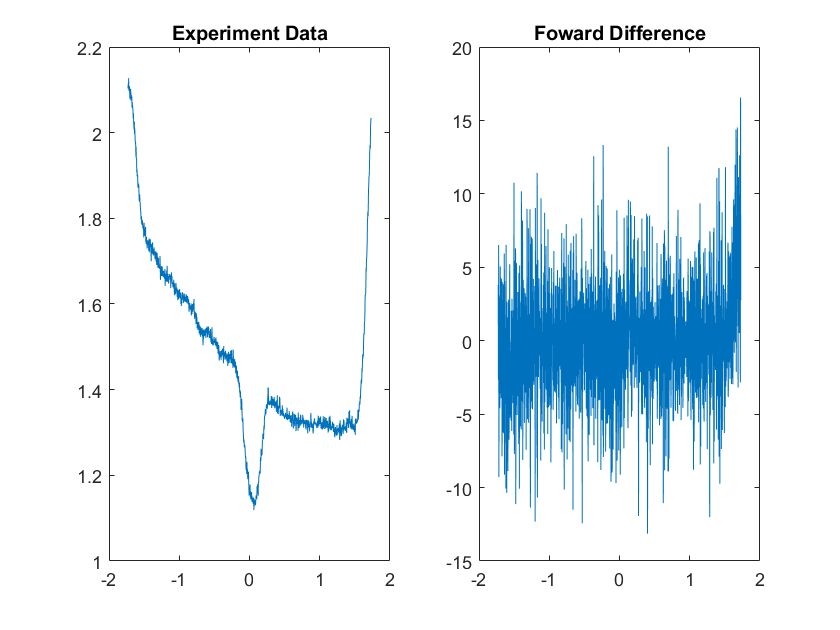

% Visualize data
clear; clc; close all;
load('Experiment.mat');
data=Experiment.Data;
label=Experiment.Label;
subplot(1,2,1)
plot(data,label)
title('Experiment Data')

dy=diff(label); FDestimate=dy/(data(2)-data(1));
subplot(1,2,2)
plot(data(1:end-1),FDestimate)
title('Foward Difference')

An alternative approach is to first smooth the data and then apply finite differences again. 

While this approach can effectively reduce noise, it is important to note that smoothing the data may also introduce distortion.

## 2. Denoising using Neural Networks

Curve fitting is another viable method,  in order to capture the essential patterns, 

the fitted curve must effectively filter out the noise without excessively smoothing the data, 

This is where neural networks (NNs) come into play.

% NN Set Up
NN.Cost='SSE';
NN.LabelAutoScaling='on';
InputDimension=1; OutputDimension=1;
LayerStruct=[InputDimension,8,8,10,OutputDimension];
NN=Initialization(LayerStruct,NN);
% Solver Set Up
option.MaxIteration=400;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 5 , Cost :    1073.02344946 
Iteration : 10 , Cost :     971.41283905 
Iteration : 15 , Cost :     549.72350728 
Iteration : 20 , Cost :     352.16353396 
Iteration : 25 , Cost :     321.78608994 
Iteration : 30 , Cost :     308.14693563 
Iteration : 35 , Cost :     257.12990895 
Iteration : 40 , Cost :     238.52916482 
Iteration : 45 , Cost :     228.64655283 
Iteration : 50 , Cost :     226.14558150 
Iteration : 55 , Cost :     219.11271329 
Iteration : 60 , Cost :     214.76388668 
Iteration : 65 , Cost :     211.50428341 
Iteration : 70 , Cost :     209.27643468 
Iteration : 75 , Cost :     207.17984691 
Iteration : 80 , Cost :     205.49654179 
Iteration : 85 , Cost :     202.64921058 
Iteration : 90 , Cost :     200.27032672 
Iteration : 95 , Cost :     198.65453594 
Iteration : 100 , Cost :     197.89108846 
------------------------------------------------------
First Stage Optimization Finished in  100  Iteration.
---------------------------------------------------

option.Solver='BFGS'; % use Quasi-Newton Solver for faster convergence
option.MaxIteration=300;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 15 , Cost :       2.48902852 
Iteration : 30 , Cost :       2.48791730 
Iteration : 45 , Cost :       2.48411611 
Iteration : 60 , Cost :       2.47735183 
Iteration : 75 , Cost :       2.46006607 
Iteration : 90 , Cost :       2.43330803 
Iteration : 105 , Cost :       2.41956889 
Iteration : 120 , Cost :       2.41070084 
Iteration : 135 , Cost :       2.40247312 
Iteration : 150 , Cost :       2.39756043 
Iteration : 165 , Cost :       2.39279827 
Iteration : 180 , Cost :       2.38765921 
Iteration : 195 , Cost :       2.38159932 
Iteration : 210 , Cost :       2.37463555 
Iteration : 225 , Cost :       2.36778274 
Iteration : 240 , Cost :       2.36140642 
Iteration : 255 , Cost :       2.35768891 
Iteration : 270 , Cost :       2.35553210 
Iteration : 285 , Cost :       2.35272173 
Iteration : 300 , Cost :       2.34881976 
------------------------------------------------------
Max Iteration : 300 , Cost :       2.34881976 
Optimization Time :   3.3
Mean Absolute Erro

It can be observed that **neural networks are capable of **

**filtering out noise while preserving essential patterns in the data**.

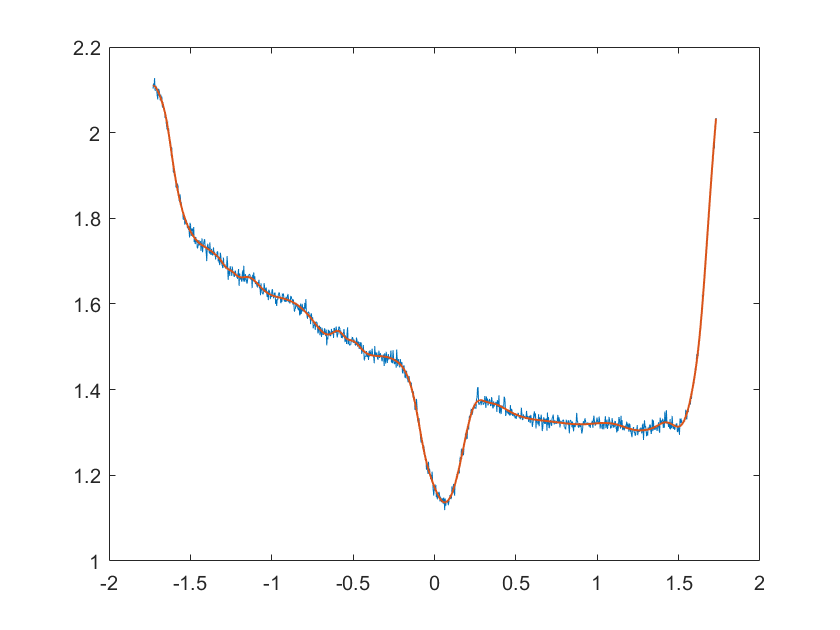

prediction=NN.Evaluate(data);
figure
plot(data,label)
hold on
plot(data,prediction,"LineWidth",1)

## 3. Computing Derivate of Neural Networks

Compute Derivate using `NN.Derivate `function.

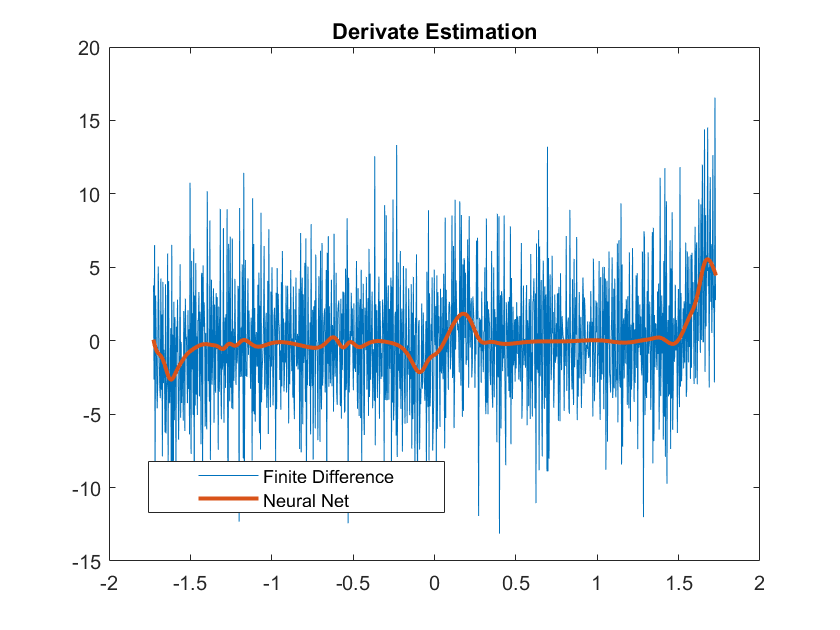

NNestimate=NN.Derivate(data(1:end-1));
% Compare with Finite Difference
figure
plot(data(1:end-1),FDestimate);
hold on
plot(data(1:end-1),NNestimate,"LineWidth",2)
legend('Finite Difference','Neural Net')
legend("Position", [0.17655,0.18611,0.35357,0.082143])
title('Derivate Estimation')

(note that the functionality of `NN.Derivate` is to compute $\frac{\partial \textrm{NN}}{\partial \mathit{\mathbf{x}}}$, not $\frac{\partial \textrm{NN}}{\partial \;\mathit{\mathbf{W}}},\frac{\partial \textrm{NN}}{\partial \;\mathit{\mathbf{b}}}$)

The function "`NN.Derivate`" implements the complex step algorithm for calculating derivatives and

can be extended to multivariable functions $\textrm{NN}\left(\mathit{\mathbf{x}}\right):R^n \to R^m$ as well. 

i.e. Jacobian (if $m=1$, then $\mathit{\mathbf{J}}$ became gradient of $\mathit{\mathbf{f}}$)


$$\textrm{NN}\left(\mathit{\mathbf{x}}\right):R^n \to R^m ,\mathit{\mathbf{J}}\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{ccc}
\frac{\partial \;{\textrm{NN}}_1 }{\partial x_1 } & \cdots  & \frac{\partial \;{\textrm{NN}}_1 }{\partial x_n }\\
\vdots  & \ddots  & \vdots \\
\frac{\partial \;{\textrm{NN}}_m }{\partial x_2 } & \cdots  & \frac{\partial \;{\textrm{NN}}_m }{\partial x_n }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\nabla {\textrm{NN}}_1 }^T \\
\vdots \\
{\nabla {\textrm{NN}}_m }^T 
\end{array}\right\rbrack$$


like most commands in MATLAB, NN.Derivate supprot matrix input, given a $N\times p$ matrix, where $p$ is number of input data points,

the function will output a $n\times p\times m$ matirx $\mathit{\mathbf{D}}$, and $\mathit{\mathbf{D}}\left(:,:,k\right)$ represent gradient of ${\textrm{NN}}_k \left(\mathit{\mathbf{x}}\right)$ evaluate at each given point ${\mathit{\mathbf{x}}}_j$.


$$\mathit{\mathbf{D}}\left(:,:,k\right)=\left\lbrack \begin{array}{cccc}
\nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_1 \right) & \nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_2 \right) & \cdots  & \nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_p \right)
\end{array}\right\rbrack ,\nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_j \right)\in R^{n\times 1}$$


With the ability to compute the derivatives of neural networks, we can apply them to various fields such as 

Surrogate Optimization and solving PDEs using neural nets (Physical-Informed Neural Networks, PINN). 